
Single objective optimization:
1 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1           2453           -52            0      0
    2           4856           -52            0      1    3           7259           -52            0      2
    4           9662           -52            0      3    5          12065           -52            0      4
Optimization finished: average change in the fitness value less than options.FunctionTolerance and constraint violation is less than options.ConstraintTolerance.


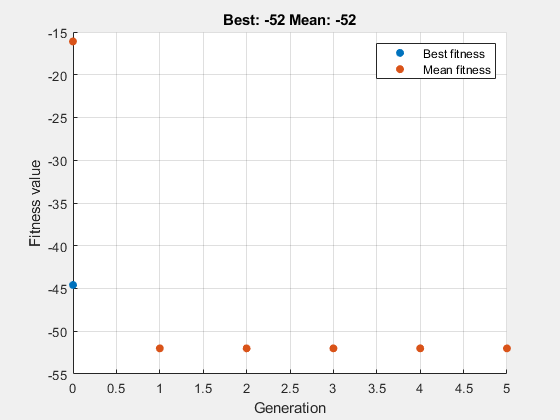

objectiveFcn = @(x) 8.*x(1) - 16 - 12.*nthroot((x(1)+4).^2, 3);

nonlincon = @(x) deal(...
    [], ...
    []);

options = optimoptions('ga', ...
    'Display', 'iter', ...
    'PlotFcn', @gaplotbestf, ...
    MaxGenerations=50);

[x_opt, fval] = ga(objectiveFcn, 1, [], [], [], [], -4, [], nonlincon, options);

disp('Оптимальное решение:');

Оптимальное решение:


disp(x_opt);

   -3.0000



disp('Минимальное значение целевой функции:');

Минимальное значение целевой функции:


disp(fval);

  -52.0000



## график

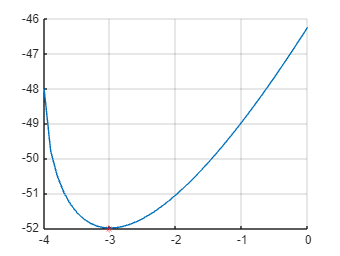


figure
x = -4:0.1:0;
f = 8.*x - 16 - 12.*nthroot((x+4).^2, 3);
hold on
plot(x, f);
plot(x_opt,fval,'*r')
grid on;